clc;
clear;
close all;

## 添加路径

addpath('plane wave\')

addpath('镜头\')

## 参数设置

# MLA

lambda = 647e-6;    % 波长
N = 80;           % 微透镜单元采样点数
rla = -0.94;            % 透镜1的曲率半径
d = 0.3;              % 透镜单元边长
t = 1;            % 透镜厚度
beamSize=2;
beamStd=beamSize/2;       %初始高斯光束腰斑直径
material={"F_SILICA"};
MLA1=Lens([rla,inf],t,d,material,lambda);
MLA2=Lens([inf,-rla],t,d,material,lambda);
num=floor(beamStd/d*6);            %数量
if num==0
    num=1;
end
area1 = num*d;           % 光场的面积
area2=30;
rate=(d/N);           %采样率（global）
area2=findClosestDivisible(area2,rate);

deltat=1;%1μs
T=100;%
times=T/deltat;
peak=0;
SD=0;
aper_array=drawRect(N*num,10/rate,0,0);
color=wavelength2color(lambda*10^6, 'gammaVal', 2.2, 'maxIntensity', 1, 'colorSpace', 'rgb');
R=linspace(0,color(1),65535)';
G=linspace(0,color(2),65535)';
B=linspace(0,color(3),65535)';
mymap=[R G B];
colormap(mymap)

# Ex-MLA

rla_ex = -2.23;            % 透镜1的曲率半径
d_ex = 0.2;              % 透镜单元边长
t_ex=t;
MLA3=Lens([rla_ex inf],t_ex,d_ex,material,lambda);
distance1 = 1;   % 投影距离
distance2 = 300;   % 投影距离
distance3=300;
distance4=4.195;

# Fourier Lens

%{
%%F=300
rfl1=-308.2;
rfl2=308.2;
dfl=50.8;
Dfl=area2;
tfl=5.1;
material_fl={'N-BK7'};
%}
%%F=100
%FL=readLens('OLD2440-T2M(JCOPTIX-F=30胶合).txt',lambda);
%%F=75
FL=readLens('Lens.txt',lambda);
Dfl=area2;
%%F=100
%FL=readLens('OLD2444-T2M(JCOPTIX-F=100胶合).txt',lambda);
beam=GaussianBeam(100,beamStd,lambda);
beams=GaussianBeam.defocused(beam,0,N*num,rate);

I=zeros(round(area2/rate));

# Diffuser

rpm=50000;%电机转速(圈每分钟)
rpus=rpm/60/1000/1000;
radius_diffuser=18;%散射片半径mm
velocity=2*pi*rpus*radius_diffuser;
diffuserAngle=0.5;   %散射片散射角度
diffuser=Diffuser(diffuserAngle,lambda);
phase=Diffuser.generateDiffuser(diffuser,rate,[round(velocity*T/rate),N*num]);

## 生成透镜相位

%%生成匀光微透镜阵列厚度函数
Lens.lensArrayThickFcn(MLA1,N,num,'square',0);
Lens.lensArrayThickFcn(MLA2,N,num,'square',0);

## 生成傅里叶透镜厚度函数

Lens.lensThickFcn(FL,Dfl,round(area2/rate));

## 生成激发微透镜阵列厚度函数

lensArray.lensArrayThickFcn2(MLA3,d_ex/rate,area2/d_ex,'square',0,d_ex-0.001,0)
%{
if size(MLA2.thick_edge,1)>size(FL.thick_edge,1)
    siz_FL=size(FL.thick_edge,1);
    siz_MLA2=size(MLA2.thick_edge,1);
    MLA2.thick_edge=MLA2.thick_edge(round((siz_MLA2-siz_FL)/2):round((siz_MLA2-siz_FL)/2)+siz_FL-1,round((siz_MLA2-siz_FL)/2):round((siz_MLA2-siz_FL)/2)+siz_FL-1,:);
    MLA2.thick_air=MLA2.thick_air(round((siz_MLA2-siz_FL)/2):round((siz_MLA2-siz_FL)/2)+siz_FL-1,round((siz_MLA2-siz_FL)/2):round((siz_MLA2-siz_FL)/2)+siz_FL-1,:);
end
%}
Lens.lensSingle(MLA1)
Lens.lensSingle(FL);
Lens.lensSingle(MLA2);
Lens.lensSingle(MLA3);
beams=single(beams);
N= single(N);
num= single(num);
Diffuser.diffuserSingle(diffuser)
rate= single(rate);
lambda= single(lambda);
distance1= single(distance1);
distance2= single(distance2);
distance3= single(distance3);
area1= single(area1);
area2= single(area2);
if canUseGPU
    Lens.lensGPUArray(MLA1)
    Lens.lensGPUArray(FL)
    Lens.lensGPUArray(MLA2);
    Lens.lensGPUArray(MLA3);
    beams=gpuArray(beams);
    N=gpuArray(N);
    num=gpuArray(num);
    Diffuser.diffuserGPUArray(diffuser)
    rate=gpuArray(rate);
    lambda=gpuArray(lambda);
    distance1=gpuArray(distance1);
    distance2=gpuArray(distance2);
    distance3=gpuArray(distance3);
    area1=gpuArray(area1);
    area2=gpuArray(area2);
end

## 光场变换

历时 6.096714 秒。
历时 10.379578 秒。


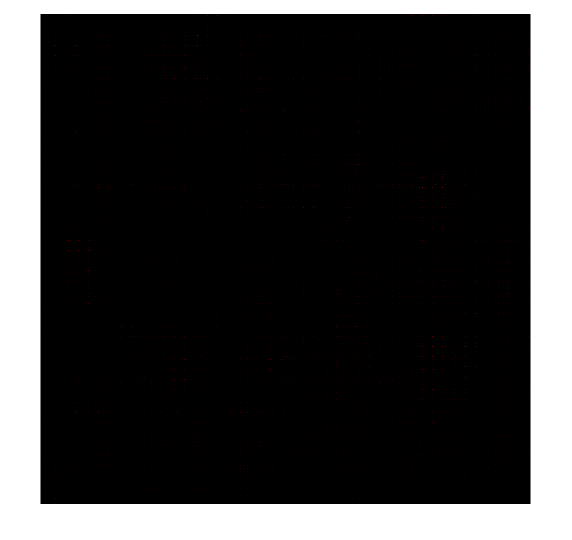

历时 14.631537 秒。


tic
for ii=1:times
    %叠加随机相位
    beamss=beams+30*randn(size(beams));
    F = transform(beamss, area1, lambda, 10, [rate, rate]);
    
    F=F.*phase(round(velocity*(ii-1)*deltat+1):round(velocity*(ii-1)*deltat+1)+1599,:);
    
    F=transform(F,area1,lambda,10,[rate, rate]);
    afterLens=ASMinLens(F,MLA1,lambda,area1);
    F = transform(afterLens, area1, lambda, distance1, [rate, rate]);
    afterLens =ASMinLens(F,MLA2,lambda,area1);
    %F=FT2Dc(afterLens);
    F = transform(afterLens, area2, lambda, distance2, [rate, rate]);
    afterLens = ASMinLens(F,FL,lambda,area2);
    F = transform(afterLens, area2, lambda, distance3, [rate, rate]);

    afterLens = ASMinLens(F,MLA3,lambda,area2);
    F = transform(afterLens, area2, lambda, distance4, [rate, rate]);
    
    %F=FT2Dc(F);
    %F=mask.*F;
    %F=FT2Dc(F);
    %F=afterLens;
    if ii==1
        I = abs(F).^2;
    else
        I = I+abs(F).^2;
    end
    %disp(ii)
    %subplot(2,1,1)
    Inorm=(I-min(I,[],'all'))./(max(I,[],'all')-min(I,[],'all'));
    imshow(uint16(Inorm*65536),mymap)
    Inorm=gather(Inorm);
    
    %if mod(ii,20)==0
    %meanFWHM=calMeanDia(Inorm,gather(ceil(d_ex/rate)*0.75),0.5)*rate;
    %disp(['平均FWHM=' num2str(meanFWHM*1e3) 'μm'])
    %end
    
    %plot(Inorm(:,3073))
    %hist=imhist(Inorm);
    %[~,peak(end+1)]=max(hist);
    %SD(end+1)=std(Inorm,0,'all');
    %subplot(2,2,3)
    %plot(peak)
    %subplot(2,2,4)
    %plot(SD)
    toc
    drawnow
end

## 显示结果

I = gather(I);
imshow(I, [])
title('Intensity on homogeneous surface')
